clc
clear
close all
set(0,'defaultAxesFontSize', 12)
set(0, 'DefaultLineLineWidth', 2);

data = load('Data/ex1data1.txt');
X = data(:, 1); % regressors matrix 
y = data(:, 2); % output
N = length(y); % number of training samples \ observations

figure; 
plot(X, y, 'rx', 'MarkerSize', 10); 
ylabel('Profit in $10,000s'); 
xlabel('Population of City in 10,000s'); 
grid on

% Setup for gradient descent
X = [ones(N, 1), data(:,1)]; % Add a column of ones to x
theta_hat = zeros(2, 1); % initialize fitting parameters

% Some gradient descent settings
iterations = 150000; % number of gradient descent iterations
alpha = 0.0001; % learning rate

% run gradient descent
theta_hat = gradientDescent(X, y, theta_hat, alpha, iterations);

% print theta to screen
fprintf('Theta found by gradient descent: ');

Theta found by gradient descent: 

fprintf('%f %f \n', theta_hat(1), theta_hat(2));

-3.877982 1.191246 


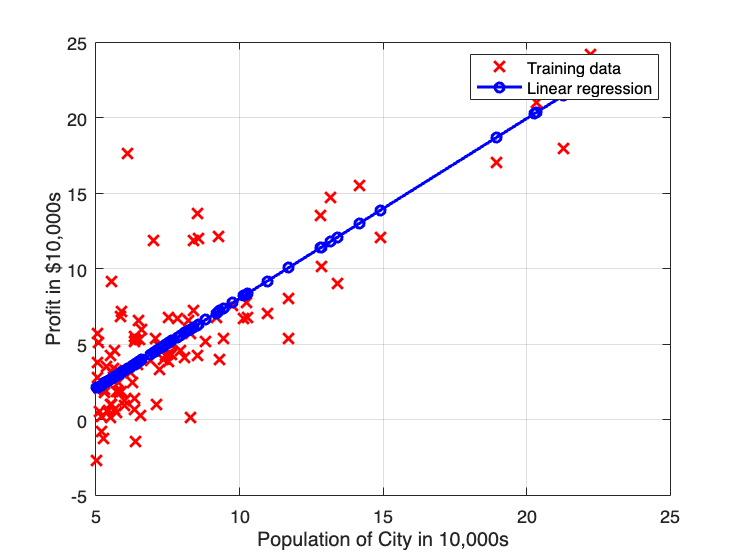


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta_hat, 'b-o')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000
profit_hat = [1, 3.5] *theta_hat;
fprintf('For population = 35,000, we predict a profit of %f\n',...
    profit_hat*10000);

For population = 35,000, we predict a profit of 2913.778240



%% Visualizing J(theta_0, theta_1)
fprintf('Visualizing J(theta_0, theta_1) ...\n')

Visualizing J(theta_0, theta_1) ...


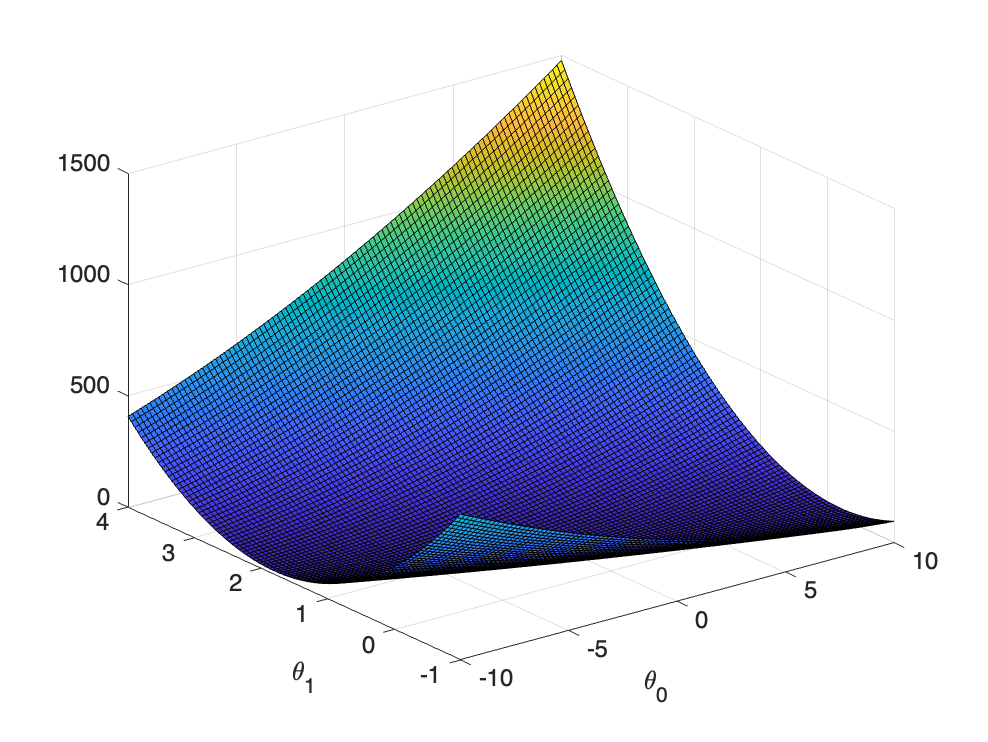


% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';
% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

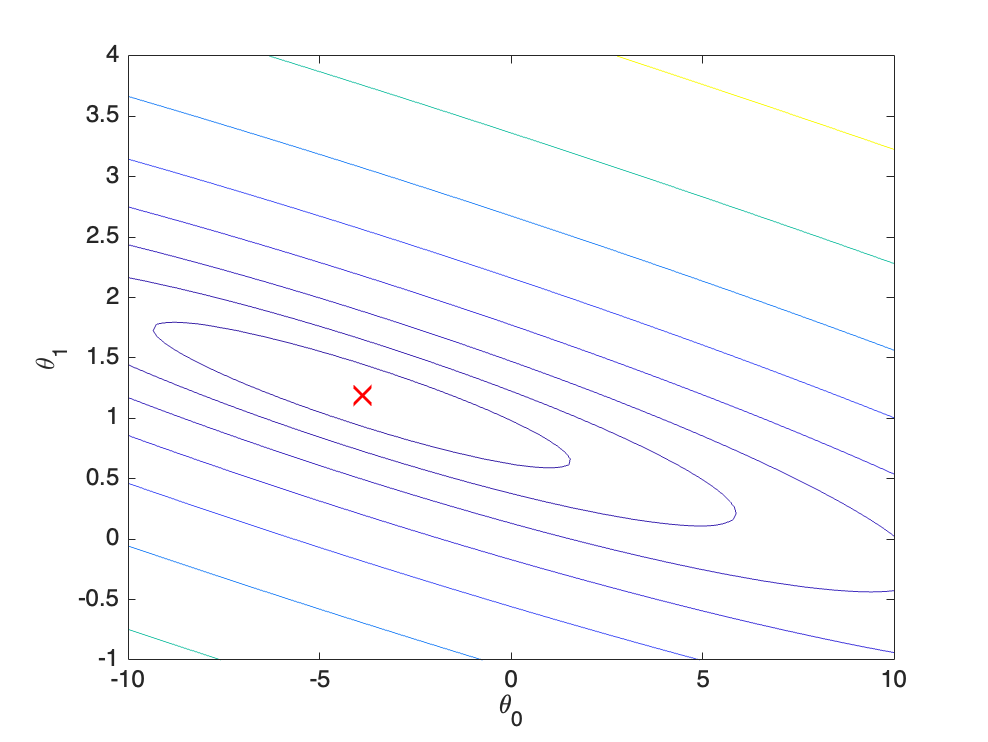


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta_hat(1), theta_hat(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);

GRADIENT DESCENT

function [theta, J_history] = gradientDescent(X, y, theta, alpha, num_iters)
N = length(y); 
J_history = zeros(num_iters, 1);

    for iter = 1:num_iters    
        theta(1,1) = theta(1,1) - alpha*((-2/N)*transpose(X(:,1))*(y-X*theta));    
        theta(2,1) = theta(2,1) - alpha*((-2/N)*transpose(X(:,2))*(y-X*theta));    
        J_history(iter) = computeCost(X, y, theta);        
    end
end

%% COMPUTE VALUE OF COST FUNCTION J
function J = computeCost(X, y, theta)
N = length(y);
J = 0;

J = (1/N)*(transpose(y)*y - 2*transpose(theta)*transpose(X)*y + transpose(theta)*transpose(X)*X*theta);
end